# Matrix Methods Applications

## Linear system applications

### Linear regression

Linear regression is a staple in both traditional fields (physics, chemistry, etc.) and newer disciplines (machine learning, data science, etc.). In general, linear regression is used to find the line of best fit to a set of data. Linear algebra is at the heart of linear regression.

**Data**

Suppose that we want to find a linear approximation for the semi-random data shown below.

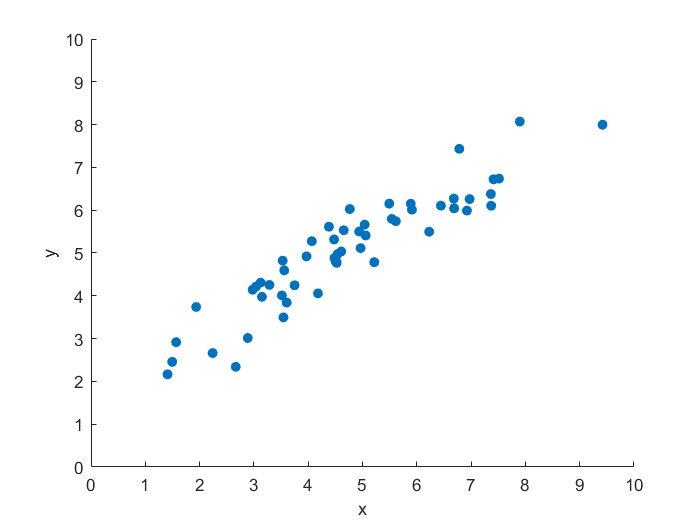

n = 55;
x = sort(normrnd(5,1.75,n,1));
y = 1*normrnd(2,0.6,n,1) + x*(0.2+rand(1,1)/2);
 
scatter(x,y,"filled")
xlabel("x")
ylabel("y")
axis tight
axis([0,10,0,10])

  **Try.** Generate the data by running this section.

**Residual**

 The relationship between $x$ and $y$ can be approximated by a linear function:

    
$$f(x) = w_0 + w_1 x$$


 Typically, the best fit line is chosen to be the one that minimizes the sum of squares error. This is error is called the residual.

    
$$R(w_0,w_1) = \sum_i [ y_i - (w_0 + w_1 x_i) ]^2$$


Visually, the residual is computed by summing the squares of the vertical differences from the line.

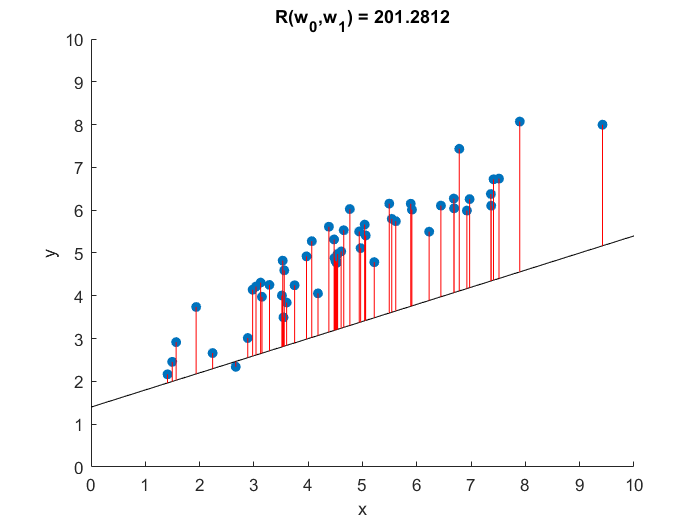

w0 = 1.4;
w1 = 0.4;
f = @(x) w0 + w1*x;
R = sum( (y - f(x)).^2 );

scatter(x,y,"filled")
hold on
plot([0,12],f([0,12]),"k-")
plot([x,x]',[f(x),y]',"r")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
axis([0,10,0,10])

  **Try.** Adjust the parameters of the linear function to reduce the sum of square error.

**Writing the linear approximation in matrix form **

To find the the parameters $w_1$ and $w_2$ that minimize the residual ($R$), you can solve for the least squares solution.

To set up this system, write the data ($x_i$ and $y_i$) in terms of vectors:

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$   and   $\mathbf{y} = \left( \matrix{ y_1 \cr y_2 \cr \vdots \cr y_n } \right)$

Then write a linear approximation vector $\tilde{\mathbf{y}} = w_0 + w_1 \mathbf{x}$ as a linear combination:

     $\tilde{\mathbf{y}} = w_0 \left( \matrix{ 1 \cr 1 \cr \vdots \cr 1} \right)
+ w_1 \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$    which is equivalent to the matrix form:     $\tilde{\mathbf{y}} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) \left( \matrix{ w_0 \cr w_1 } \right)
$.

This can be written as

    
$$\tilde\mathbf{y} = \mathbf{Xw}$$


where

    $\mathbf{X} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) $ and vector $\mathbf{w} = \left( \matrix{ w_0 \cr w_1 } \right)$.

** Exercise**. Write the approximate solution in matrix form.

1. Define the matrix $\mathbf{X}$ by concatenating a column of ones with the vector of $x$-values from the data.

X = [ones(n,1), x]

X =     1.0000    1.4093
    1.0000    1.4954
    1.0000    1.5684
    1.0000    1.9371
    1.0000    2.2402
    1.0000    2.6661
    1.0000    2.8863
    1.0000    2.9763
    1.0000    3.0398
    1.0000    3.1237


2. Define the vector $\mathbf{w}$ using the variables `w0` and `w1`.

w = [w0; w1]

w =     1.4000
    0.4000


3. Compute the linearly approximated y-values: $\tilde\mathbf{y} = \mathbf{Xw}$. Assign $\tilde{\mathbf{y}$ to the matlab variable `y_approx`.

y_approx = X*w

**Visualize the linear approximations of the data**

  **Try.** Run this section to visualize the estimates stored in `y_approx`.

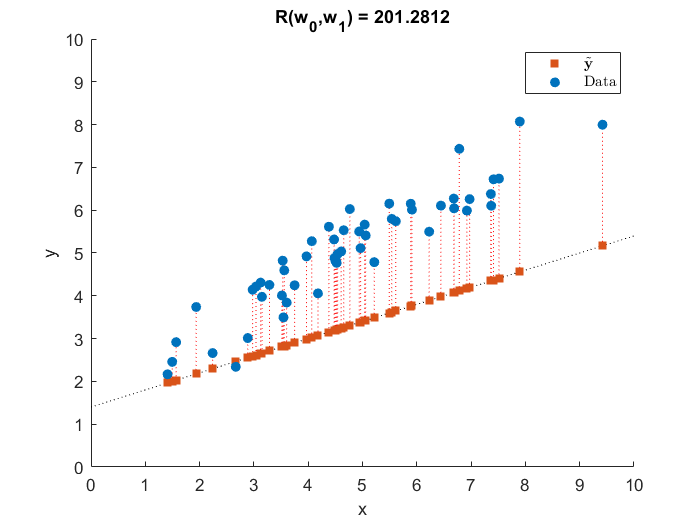

 
fls = @(x) w(1) + w(2)*x;
R = sum( (y - fls(x)).^2 );

scatter(x,y,"filled")
hold on
scatter(x,y_approx,'s',"filled")
plot([0,12],fls([0,12]),"k:")
plot([x,x]',[fls(x),y]',"r:")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
leg = legend('Data',"$\tilde{\mathbf{y}}$");
set(leg,"interpreter","latex")
axis([0,10,0,10])

chi=get(gca, 'Children');
set(gca, 'Children',flipud(chi));

**Solution to the least squares problem **

**General solution**

In the linear regression problem, you want to minimize the sum of square errors. The calculus approach is shown here. The residuals can be written in terms of the matrix elements as

    
$$\begin{array}{rl}
R(w_0,w_1) &= \sum_i [ y_i - (w_0 + w_1 x_i) ]^2
\\
 &= \sum_i (y_i - \tilde{y}_i )^2
\\
 &= \sum_i \left(y_i -  \sum_j X_{ij} w_{j} \right)^2
\end{array}
$$


To minimize this equation with respect to $w_i$ using a calculus approach, find the stationary points. To do so, take the derivative $\frac{\partial}{\partial w_k}$ and set it equal to zero:

    
$$\begin{array}{rl}
\frac{\partial}{\partial w_k} R(w_0,w_1)  &= \sum_i 2\left( y_i - \sum_j X_{ij} w_{j} \right) \frac{\partial}{\partial w_k} \left(y_i - \sum_j  X_{ij} w_{j} \right)
\\
0 &= 2\sum_i  \left( y_i - \sum_j X_{ij} w_{j} \right) ( - X_{ik} )
\\
0 &= \sum_i  - y_i X_{ik} + \sum_{ij} X_{ij} w_{j} X_{ik} 
\end{array}
$$


This final set of sums can be written in matrix notation:

    
$$\begin{array}{rl}
0 &= -\mathbf{y}^\top \mathbf{X} + \mathbf{X}^\top \mathbf{X}\mathbf{w} 
\\
\mathbf{X}^\top \mathbf{X}\mathbf{w} & = \mathbf{X}^\top \mathbf{y}
\end{array}$$


Note that so far this only shows that this is a critical point. An additional argument (not shown here) is required to demonstrate that this indeed minimizes the residual (this is however intuitive due to the original quadratic form of the residual).

To solve this system for the coefficients $\mathbf{w}$, you can use any standard method for solving a matrix system. Compare this form of this equation to the standard form:

    
$$\mathbf{X}^\top \mathbf{X}\mathbf{w}  = \mathbf{X}^\top \mathbf{y}$$
 
$$\Leftrightarrow$$

$$\mathbf{Aw} = \mathbf{b}$$
 

        where $\mathbf{A} = \mathbf{X}^\top \mathbf{X}$ and $\mathbf{b} = \mathbf{X}^\top \mathbf{y}$.

**Specific solution**

** Exercise**. You can use this method to find the least squares solution to the example data. To do so, you can define the matrix $\mathbf{A}$ and RHS vector $\mathbf{b}$ and then solve for the matrix solution.

1. Compute the matrix `A` and RHS vector `b` using the formulas $\mathbf{A} = \mathbf{X}^\top \mathbf{X}$ and $\mathbf{b} = \mathbf{X}^\top \mathbf{y}$.

A = X'*X

A = 	1.0e+03 *

    0.0550    0.2664
    0.2664    1.4873


b = X'*y

b = 	1.0e+03 *

    0.2811
    1.4942


2. Compute matrix solution using the backslash operator.

w = A\b

w =     1.8556
    0.6722


Note: you don't actually have to define `A` and `b` to compute the solution. You could simply use their expressions directly.

**Visualize the least squares fit**

  **Try.** Once your solution is complete (i.e., you have solved for $\mathbf{w}$), you can view the least squares solution by running this section.

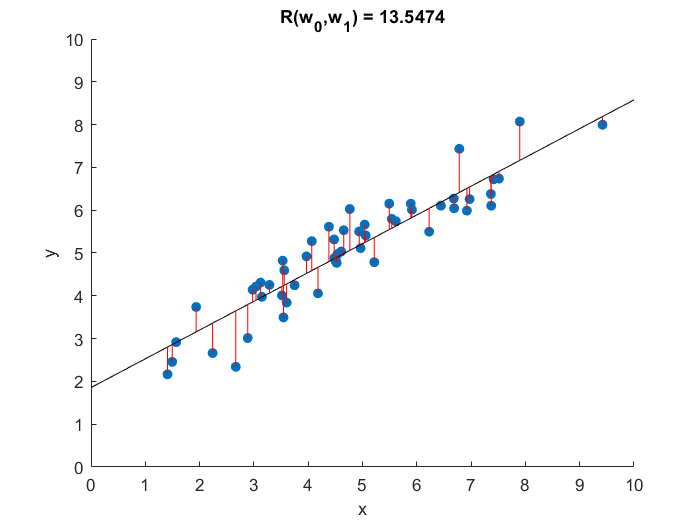

 
fls = @(x) w(1) + w(2)*x;
R = sum( (y - fls(x)).^2 );
scatter(x,y,"filled")
hold on
plot([0,12],fls([0,12]),"k-")
plot([x,x]',[fls(x),y]',"r")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
axis([0,10,0,10])

- How close was your by-hand fit residual to the least squares fit residual?

### Linear circuits

Simple linear circuits can be analyzed using Kirchoff's circuit laws. Matrices provide a natural framework: they can concisely capture the many linear equations that model the circuit network.

**Kirchhoff's current law**

The sum of all currents flowing into a node equals the sum of currents flowing out of the node.

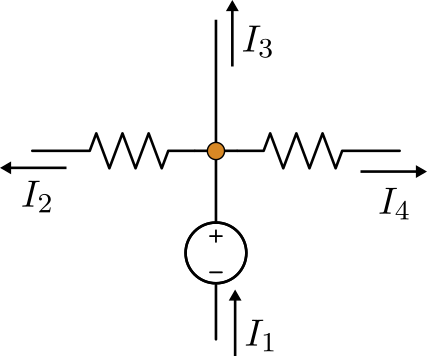

*At this node, Kirchhoff's current law implies *$I_1 = I_2 + I_3 + I_4 $

**Kirchhoff's voltage law**

The sum of voltages around a closed loop of a circuit is zero. Mathematically:

    
$$\sum_{k} V_k = 0$$


where $V_k$ is the potential difference across the $k^{th}$ branch of the circuit. Applying Ohm's law gives the potential drop across each resistor: $V = IR$.

 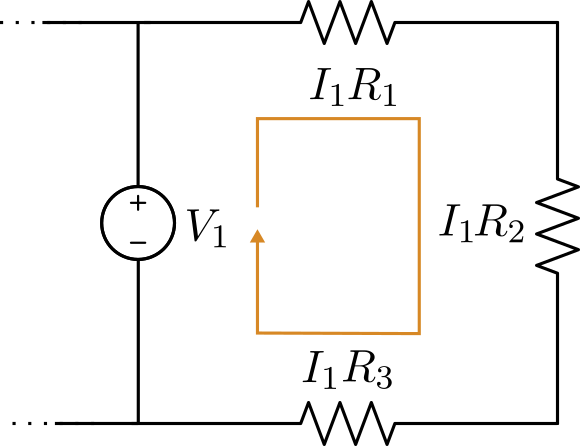

*The potential drop across the resistors in this closed loop must equal the potential generated by the voltage source: *$V_1 - I_1 R_1 - I_1 R_2 - I_1 R_3 = 0$

**Matrix representation of a circuit**

In this section, the pictured linear circuit will be analyzed using Kirchhoff's laws, written in matrix form.

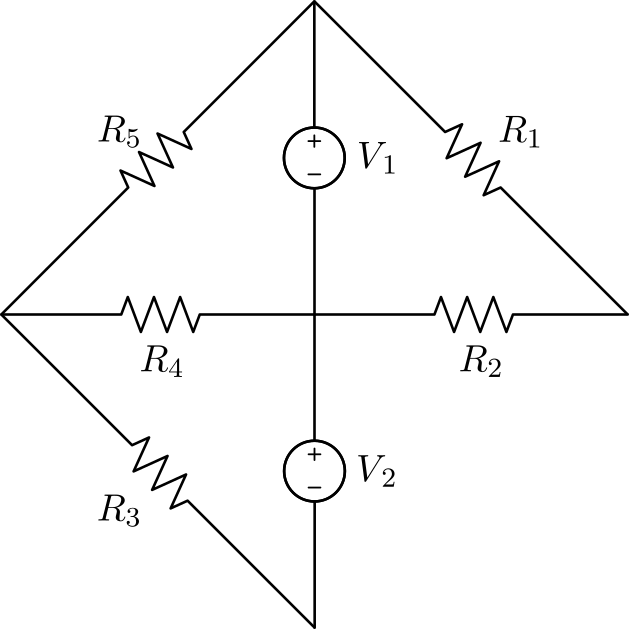

*The circuit to be analyzed*

**Derivation of the equations**

Before writing the equations, it is useful to define current paths through the circuit. This provides a framework for applying Kirchhoff's laws. Note that the current paths are arbitrary, as current flowing in the opposite direction will simply be represented as a negative value. However, the chosen reference directions determine the correct form of Kirchhoff's laws.

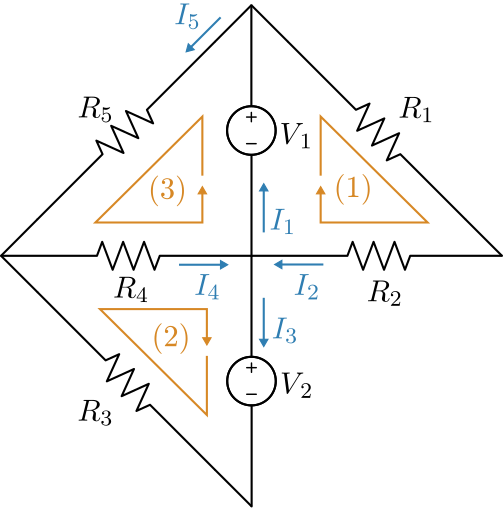

*In this diagram, three closed loops of the circuit are labeled (1), (2), and (3). The distinct currents in the circuit are also labeled*

Applying **Kirchhoff's current law** to the central node yields:

    
$$I_2 + I_4 = I_1 + I_3$$


Applying **Kirchhoff's voltage law **to the three loops adds three additional equations:

    
$$\begin{array}{rl} 
\ V_1 - I_2 R_1 - I_2 R_2  &= 0
\\
- V_2 - I_3 R_3 - I_4 R_4  &= 0
\\
\ V_1 - I_5 R_5 - I_4 R_4  &= 0
\end{array}$$


At this point, we have 5 unknown currents, but only four equations. To complete the representation, another application of the Kirchhoff's current law is required. For the top node:

    
$$I_1 = I_2 + I_5$$


Note that there are loops and nodes to which you can apply Kirchhoff's law – but all of them are redundant.

**Derivation of the matrix form of the equations**

To write these equations in matrix form $\mathbf{AI} = \mathbf{b}$, define the solution vector 

    
$$\mathbf{I} = \left( \matrix{ I_1 \cr I_2 \cr I_3 \cr I_4 \cr I_5 } \right)$$


Moving all variable terms to the LHS and constant terms to the RHS implies:

     $\begin{array}{rl} 
\ I_2 R_1 + I_2 R_2  &= V_1
\\
I_3 R_3 + I_4 R_4  &=  -V_2
\\
I_5 R_5  + I_4 R_4  &= V_1  
\\
I_1 - I_2 + I_3 - I_4 &= 0
\\
I_1 - I_2 - I_5 &= 0
\end{array}$        (1)

** Exercise**.

(a) Rewrite the system (1) in matrix form $\mathbf{AI} = \mathbf{b}$ by determining the form of $\mathbf{A}$ and $\mathbf{b}$.

showSolution = false;
if(showSolution)
    showCircuitMatrices() 
end

(b) Compute the matrix product $\mathbf{AI}$ to verify that the matrix form matches the original system (1).

**Solutions to the matrix system**

**Specific solution. **

** Exercise**. Suppose that the resistors and voltage sources have values:

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 100 \ \Omega
\\
R_3 = 10 \ \Omega
\\
R_4 = 1 \ k\Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 1.5 \ \text{V}
\end{array}$$


What are the currents through the circuit?

**Hint: **Solve for the current by defining the numeric matrix A, the RHS vector b, and then applying the backslash operator (\). 

A = [0 110  0   0   0; 
     0   0 10 1e3   0;
     0   0  0 1e3 330;
     1  -1  1  -1   0;
     1  -1  0   0  -1]

A =            0         110           0           0           0
           0           0          10        1000           0
           0           0           0        1000         330
           1          -1           1          -1           0
           1          -1           0           0          -1


b = [1.5 -1.5 1.5 0 0]'

b =     1.5000
   -1.5000
    1.5000
         0
         0


I = A\b

I =     0.0224
    0.0136
   -0.0102
   -0.0014
    0.0088


**General solution.** 

** Exercise**. Use symbolic math to find currents through this circuit for arbitrary resitances and voltages. 

Define symbolic variables for the resistances and voltages (e.g.,` syms R_1 V_1 `).

syms R_1 R_2 R_3 R_4 R_5 V_1 V_2


(a) Solve for the current by defining the matrix A, the RHS vector b, and then applying the backslash operator (\) to solve for the currents.

A = [0 R_1+R_2   0   0   0; 
     0       0 R_3 R_4   0;
     0       0  0  R_4 R_5;
     1      -1  1   -1   0;
     1      -1  0    0  -1]

$$A = \left(\begin{array}{ccccc} 0 & R_{1}+R_{2} & 0 & 0 & 0\\ 0 & 0 & R_{3} & R_{4} & 0\\ 0 & 0 & 0 & R_{4} & R_{5}\\ 1 & -1 & 1 & -1 & 0\\ 1 & -1 & 0 & 0 & -1 \end{array}\right)$$

b = [V_1; -V_2; V_1; 0; 0]

$$b = \left(\begin{array}{c} V_{1}\\ -V_{2}\\ V_{1}\\ 0\\ 0 \end{array}\right)$$

I = A\b

$$I = \begin{array}{l} \left(\begin{array}{c} \frac{R_{1}\,R_{3}\,V_{1}+R_{1}\,R_{4}\,V_{1}+R_{2}\,R_{3}\,V_{1}+R_{1}\,R_{4}\,V_{2}+R_{2}\,R_{4}\,V_{1}+R_{2}\,R_{4}\,V_{2}+R_{3}\,R_{4}\,V_{1}+R_{3}\,R_{5}\,V_{1}+R_{4}\,R_{5}\,V_{1}}{\left(R_{1}+R_{2}\right)\,\sigma_{1}}\\ \frac{V_{1}}{R_{1}+R_{2}}\\ -\frac{R_{4}\,V_{1}+R_{4}\,V_{2}+R_{5}\,V_{2}}{\sigma_{1}}\\ \frac{R_{3}\,V_{1}-R_{5}\,V_{2}}{\sigma_{1}}\\ \frac{R_{3}\,V_{1}+R_{4}\,V_{1}+R_{4}\,V_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{3}\,R_{4}+R_{3}\,R_{5}+R_{4}\,R_{5} \end{array}$$

(b) Evaluate the general symbolic solution computed in (a) for the specific solution with parameters

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 100 \ \Omega
\\
R_3 = 10 \ \Omega
\\
R_4 = 1 \ k\Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 1.5 \ \text{V}
\end{array}$$


**Hint:** You can evaluate the symbolic solution for specific values of the variables in MATLAB. To do so, use [`matlabFunction`](https://www.mathworks.com/help/symbolic/matlabfunction.html) to generate a MATLAB function handle and then evaluate it with the specific values of the parameters.

Ifunc = matlabFunction(I)

Ifunc = function_handle with value:
    @(R_1,R_2,R_3,R_4,R_5,V_1,V_2)[(R_1.*R_3.*V_1+R_1.*R_4.*V_1+R_2.*R_3.*V_1+R_1.*R_4.*V_2+R_2.*R_4.*V_1+R_2.*R_4.*V_2+R_3.*R_4.*V_1+R_3.*R_5.*V_1+R_4.*R_5.*V_1)./((R_1+R_2).*(R_3.*R_4+R_3.*R_5+R_4.*R_5));V_1./(R_1+R_2);-(R_4.*V_1+R_4.*V_2+R_5.*V_2)./(R_3.*R_4+R_3.*R_5+R_4.*R_5);(R_3.*V_1-R_5.*V_2)./(R_3.*R_4+R_3.*R_5+R_4.*R_5);(R_3.*V_1+R_4.*V_1+R_4.*V_2)./(R_3.*R_4+R_3.*R_5+R_4.*R_5)]


Ifunc(10,100,10,1e3,330,1.5,1.5)

ans =     0.0224
    0.0136
   -0.0102
   -0.0014
    0.0088


## **Eigen analysis applications**

### **Vibrating masses**

**Physical system and the equations of motion**

Consider a system of $n$ masses connected by a string with uniform tension $T$ between each mass.

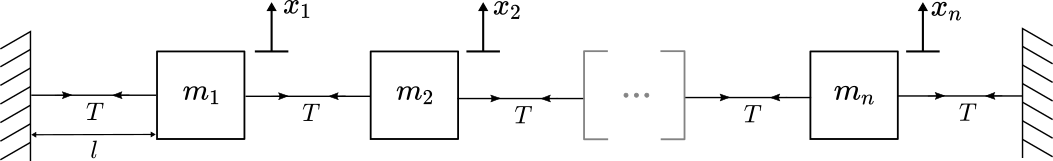

*System of equally spaced connected masses*

Assume additionally that each mass may only be displaced in the vertical direction. You can draw a free body diagram for $i^{th}$ mass and use it to derive the equations of motion.

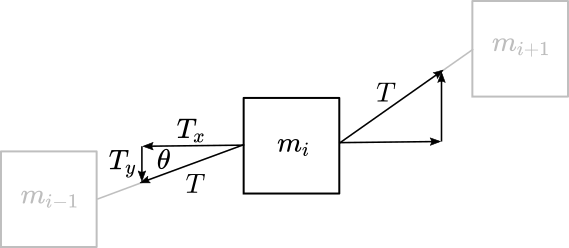

*Free body diagram for the *$i^{th}$* mass*

The angle $\theta$ can be related to the displacements. Note that in this calculation we assume that the displacement is small, so that the horizontal distance between the masses $\approx l$.

    
$$\sin \theta = \frac{x_i - x_{i-1}}{l}$$


The force acting in the $y$-direction is

    
$$\begin{array}{rl} T_y &= T \sin \theta \\ &= \frac{T}{l} (x_i - x_{i-1}) \end{array}$$


Performing the same analysis on the other side of the mass yields a similar result. Applying Newton's second law yields:

    
$$\begin{array}{rl}
m_i \ddot{x}_i &= \frac{T}{l}( - x_i + x_{i-1} )  + \frac{T}{l}(x_{i+1} - x_{i} ) 
\\
m_i \ddot{x}_i &= \frac{T}{l}( x_{i-1} - 2x_i + x_{i+1} )
\end{array}$$


For simplicity of the analysis, assume $m_i = T = l = 1$, yielding:

   
$$\begin{array}{rl}
\ddot{x}_i &=  x_{i-1} - 2x_i + x_{i+1} 
\end{array}$$


for each mass. Note that for the first and last mass the equations are identical but lack the displacements of the missing neighbor:

   
$$\begin{array}{rl}
\ddot{x}_1 &=  - 2x_i + x_{i+1} 
\\
\ddot{x}_n &=  x_{n-1} - 2x_n 
\end{array}$$


**Matrix form of the equations of motion**

To represent this system in matrix form, define a solution vector

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$.

Then the equations of motion can be written as

    
$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


  **Task. **Define the number of masses in the system (this definition will be used througout the remainder of this example).

n = 7;      % Number of masses
 

** Exercise**. Base on the definition of $\mathbf{x}$ and the ODE

   
$$\begin{array}{rl}
\ddot{x}_i &=  x_{i-1} - 2x_i + x_{i+1} 
\end{array}$$


what will  the form of $\mathbf{A}$ be in the matrix form of the ODE system, $\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$?

showSolution = true;
if(showSolution)
    AForm(n)
end

$$A = \left(\begin{array}{ccccccc} -2 & 1 & 0 & 0 & 0 & 0 & 0\\ 1 & -2 & 1 & 0 & 0 & 0 & 0\\ 0 & 1 & -2 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & -2 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & -2 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 & -2 & 1\\ 0 & 0 & 0 & 0 & 0 & 1 & -2 \end{array}\right)$$

** Exercise**. Define the numeric matrix $\mathbf{A$ in MATLAB for an arbitrary number of masses $n$.

  **Pro-tip**: Use the [`diag`](https://www.mathworks.com/help/matlab/ref/diag.html) function to create three diagonal matrices and sum the result with the correct coefficients.

% Define the matrix A
A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1)

A =     -2     1     0     0     0     0     0
     1    -2     1     0     0     0     0
     0     1    -2     1     0     0     0
     0     0     1    -2     1     0     0
     0     0     0     1    -2     1     0
     0     0     0     0     1    -2     1
     0     0     0     0     0     1    -2


**Solution to the ODE system in MATLAB**

The ODE system 

    
$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


is solved here using a numeric ODE solver. In this process, the ODE is integrated to yield a solution $\mathbf{x}(t)$ given a initial conditions $\mathbf{x}(0)$ and $\dot\mathbf{x}(0)$.

  **Task. **Run the section to see the solution. Notice how compact the ODE implementation is by examing the function `odeStringMasses`. Matrix representations, like this one, are particularly useful when writing code.

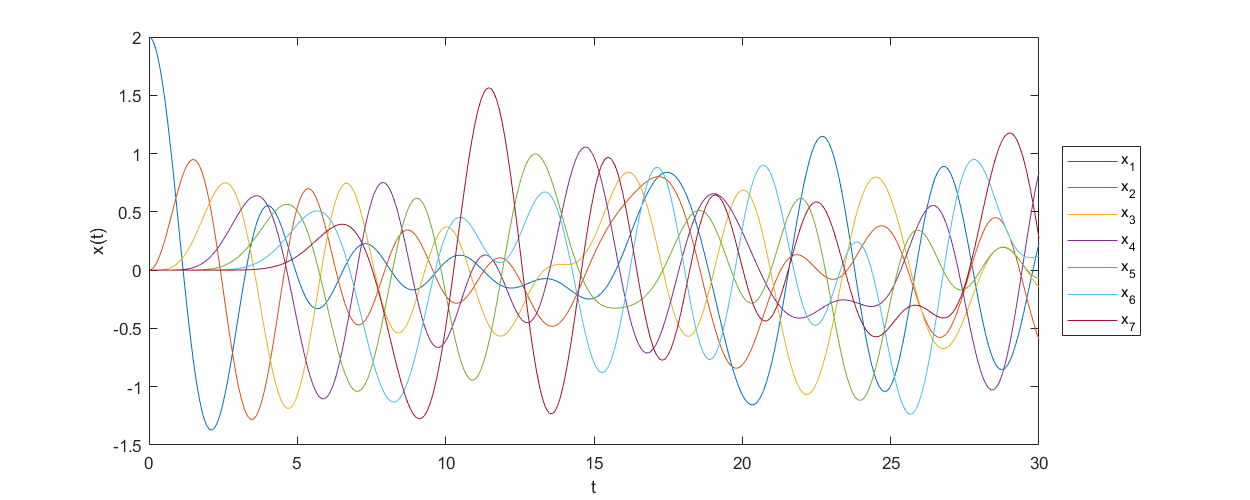

x01 = 2;   % Initial displacement of the first mass
tf =30;     % Duration of the simulation
 

x0 = zeros(n,1);
x0(1) = x01;
tlim = [0,tf]; 
[t,x,xdot] = solveMassesODE(x0, tlim, n);

figure('Position',[100,200,1000,400])
plot(t,x)
xlabel("t")
ylabel("x(t)")
legend("x_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

  **Try**. 

- Adjust the number of masses `n` above and rerun the simulation. Does the natural oscillation frequency change?

- Adjust the initial displacement and duration of the simulation. What happens as $t$ becomes large?

**Visualize the motion**

The graph of displacements can be difficult to relate to physical experience. Try checking the box to visualize the motion of the masses.

Nframes = 190; % Adjust the number of frames to speed up or slow down the animation
solveAndVisualize = false;
if(solveAndVisualize)
    tlim = [0,tf]; 
    [t,x,xdot] = solveMassesODE(x0, tlim, n);
    animateODEMasses(t,x,Nframes)
end 

**Eigenvectors and natural oscillation modes**

The natural modes of oscillation of the connected mass system can be identified by computing the eigenvectors of the coefficient matrix.

** Exercise**. Compute the eigen decompoision of $\mathbf{A$ in MATLAB.

% The coefficient matrix
A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
% Compute the eigenvectors and eigenvalues
[V,D] = eig(A)

V =     0.1913   -0.3536    0.4619    0.5000    0.4619   -0.3536   -0.1913
   -0.3536    0.5000   -0.3536   -0.0000    0.3536   -0.5000   -0.3536
    0.4619   -0.3536   -0.1913   -0.5000   -0.1913   -0.3536   -0.4619
   -0.5000    0.0000    0.5000    0.0000   -0.5000    0.0000   -0.5000
    0.4619    0.3536   -0.1913    0.5000   -0.1913    0.3536   -0.4619
   -0.3536   -0.5000   -0.3536    0.0000    0.3536    0.5000   -0.3536
    0.1913    0.3536    0.4619   -0.5000    0.4619    0.3536   -0.1913


D =    -3.8478         0         0         0         0         0         0
         0   -3.4142         0         0         0         0         0
         0         0   -2.7654         0         0         0         0
         0         0         0   -2.0000         0         0         0
         0         0         0         0   -1.2346         0         0
         0         0         0         0         0   -0.5858         0
         0         0         0         0         0         0   -0.1522


  **Try**. Plot the eigenvectors (the columns of the $\mathbf{V}$ in the eigen decomposition of $\mathbf{A}$) using the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html#d122e958554) function.

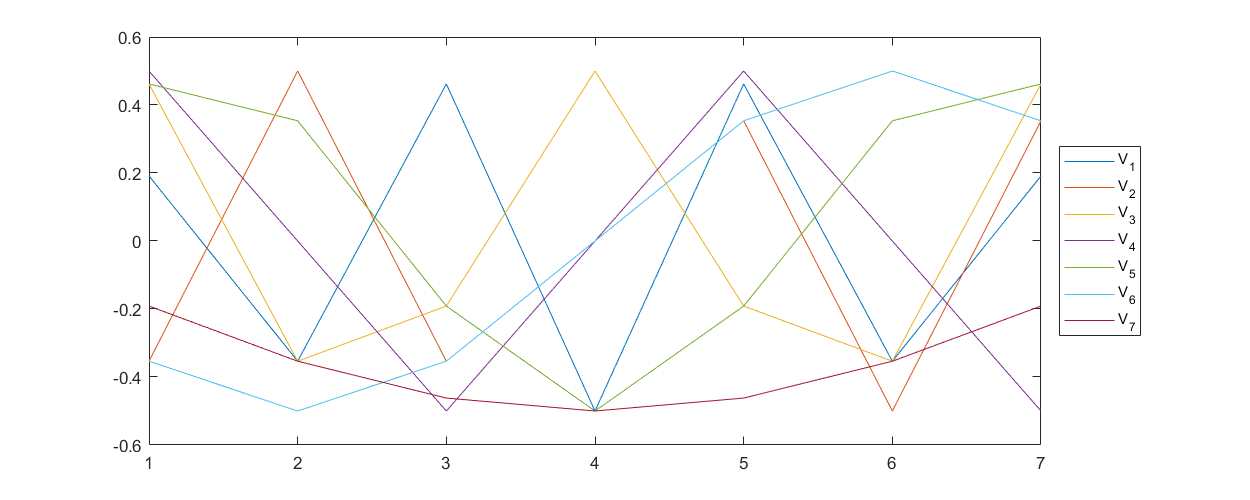

figure('Position',[100,200,1000,400])
% Plot V here
plot(V)

% This adds a legend to the graph
legend("V_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

These eigenvectors actually represent the diplacements of the masses according to a particular natural mode of oscillation. This section visualizes the eigenvectors with the masses shown.

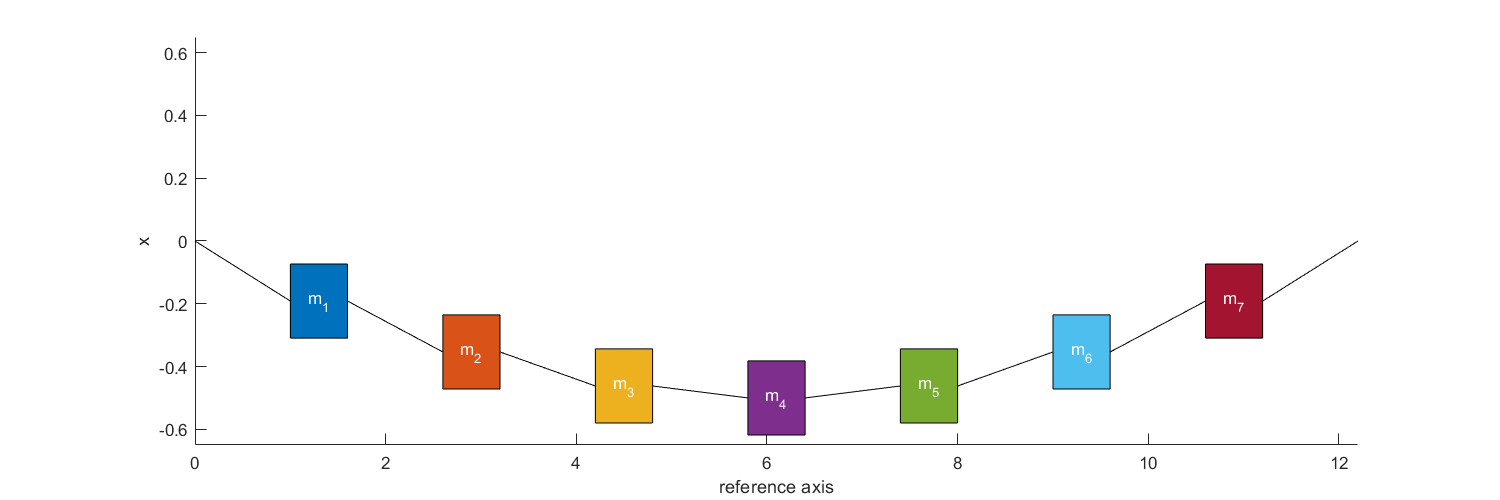

modeIndex = 7; % The mode index must be <= the number of masses
 

visualizeMasses(V(:,modeIndex))

  **Try**. Adjust the mode index to view the natural vibrational modes.

 **Reflect. **Based on the simulation output, which mode do you think is dominant in the simulation generated above?

**Computation of the modes present in the ODE solution**

The eigenvectors provide an alternative basis for the motion of masses. You can compute which mode is dominant for this simulation by expressing the solution in terms of the eigenvector basis:

    
$$\mathbf{x} = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


The coefficients $\mathbf{b}$ determine the presence of each mode.

In matrix form:

    
$$\mathbf{x} = \mathbf{V} \mathbf{b}$$


To solve for the mode coefficients, at any time $t$, the matrix solution for $\mathbf{b}$ can be computed.

** Exercise**. Solve for the mode coefficients at the last time step in the simulation. 

  **Pro-tip**: To access the values of $\mathbf{x}$ in the last time step, use:

xf = x(end,:)'

xf =     0.2269
   -0.5924
   -0.1456
    0.8391
   -0.0682
    0.1197
    0.2734


bf = V\xf

bf =    -0.2555
   -0.3123
    0.8587
    0.0154
   -0.3147
    0.3998
   -0.2494


This loop computes the coefficients of the eigenmodes over the whole simulation.

% Compute the coefficients b
b = zeros(size(x));
for k = 1:length(t)
    b(k,:) = V\x(k,:)';
end

  **Try**. Plot the eigenmode coefficients stored in `b` against `t` using the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html#d122e958554) function.

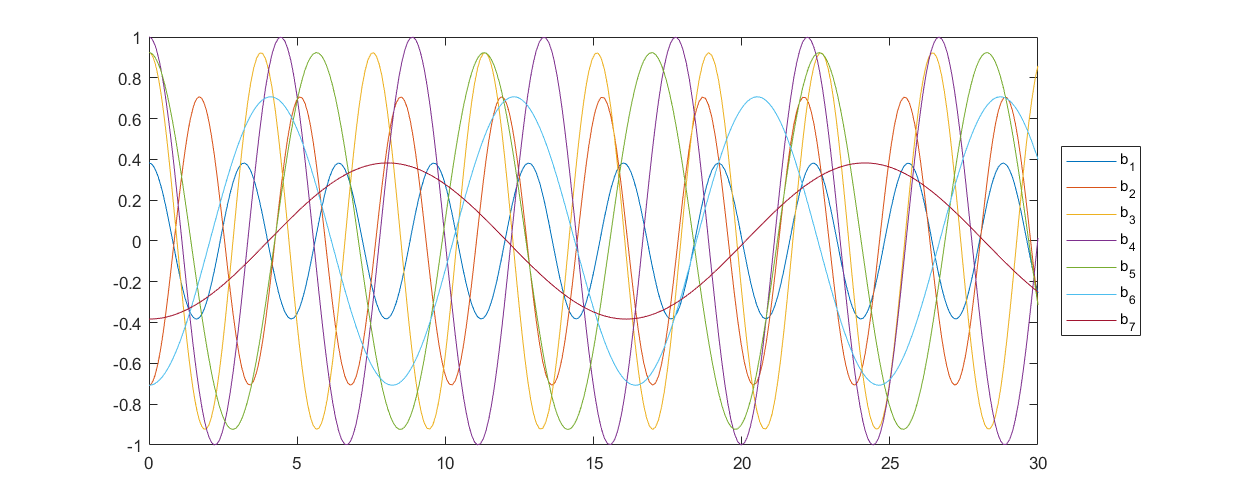

figure('Position',[100,200,1000,400])
% Plot b here
plot(t,b)

% This adds a legend to the plot
legend("b_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

 **Reflect. **

- Which mode is dominant in this solution?

- What are the periods of oscillation of each mode?

**Eigenmode solutions**

In this losseless system, an arbitrary solution can be constructed as a sum of the natural oscillation modes. To do so, you can set the inital displacement of the system to a sum of the natural modes:

        
$$\mathbf{x}_0 = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


The system will continue to oscillate with those natural modes indefinitely as there is no damping term in the equation. 

  **Task**.  Define the $n$-element mode coefficient vector $\mathbf{b}$ to determine which modes will be present in the simulation. 

b = [0 0 0 0 0 0 1]'    

b =      0
     0
     0
     0
     0
     0
     1


  **Task**. Compute the initial condition vector $\mathbf{x}_0$ based on the vector $\mathbf{b}$ and the eigenvector matrix $\mathbf{V}$.

x0 = V*b

x0 =    -0.1913
   -0.3536
   -0.4619
   -0.5000
   -0.4619
   -0.3536
   -0.1913


**Visualize the motion**

Check the box to run this section, compute the  ODE solution, and visualize the solution.

tf =20;     % Duration of the simulation
Nframes = 130; % Adjust the number of frames to speed up or slow down the animation
solveAndVisualize = false;
if(solveAndVisualize)
    tlim = [0,tf]; 
    [t,x,xdot] = solveMassesODE(x0, tlim, n);
    animateODEMasses(t,x,Nframes)
end 

You can also compute the coefficients of the eigenmodes over time. Run this section to view the coefficients over time.

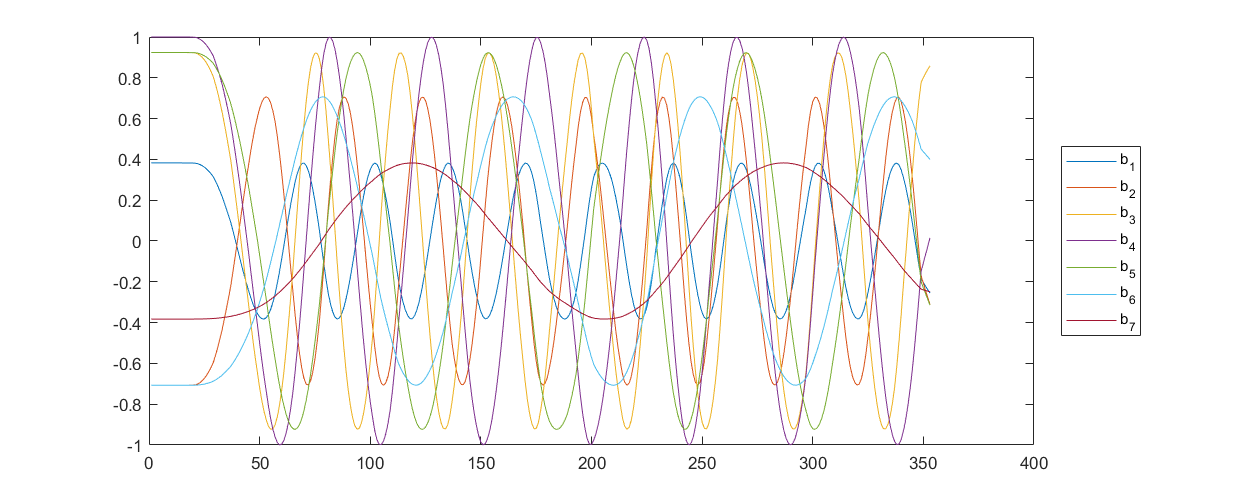

 
% Compute the coefficients b
b = zeros(size(x));
for k = 1:length(t)
    b(k,:) = V\x(k,:)';
end
% Plot them
figure('Position',[100,200,1000,400])
plot(b)
legend("b_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

 **Reflect. **

- Is energy transferred between eigenmodes?

### Risk Assessment using a Markov chain 

**Background**

Suppose that a car insurance company has classified clients in five categories of risk.

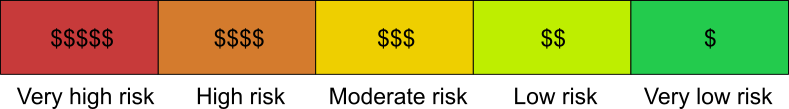

*Risk categories. High risk clients pay higher premiums because they are more likely to require a payout on a claim.*

Each year, the risk of a client is reassessed. Clients will be moved between categories based on their history. For example

- Being at fault in an accident will move a client into a higher risk category

- Having a year without an incident could move the client into a lower risk category

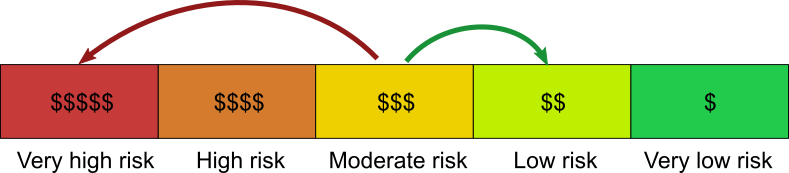

*Twp possible transitions of clients between categories.*

A Markov chain can be used to model how the pool of clients will change based on a the history of how clients have moved between categories. The client history is represented as a probability (over 1 year) that a client will move into another category or stay in the same category.

The goal of the model is to determine how the distribution of clients in different risk categories will change in the future based on the history of how clients have moved between risk categories in the past.

**Transitions**

Let the fraction of clients in a given category be modeled by

    
$$\mathbf{r} = \left( \matrix{ r_1 \cr r_2 \cr r_3 \cr r_4 \cr r_5 } \right)$$


Each variable $r_i$ represents the fraction of clients in each risk category (with all clients $= \sum_i r_i = 1$). The lowest risk being represented by $r_5$ and $r_1$ indicating very high risk. In each year, a client has a probability that they will move into another category or remain in that same cateogry. 

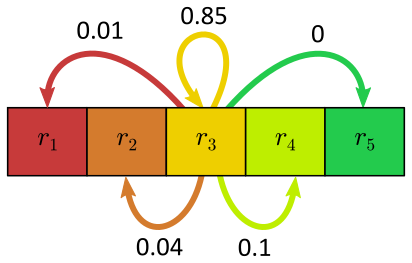

*Likelihoods for *$r_3$* clients. On average 85% remain in *$r_3$ each year. A few move into other categories. However, 0% will move into $r_5$, since they will have to pass through the low risk ($r_4$) category first.

Notice that the total probability of transitions out of $r_3$ are equal to 1. These transitions are just one set of probabilities. In fact, there are 5 sets of transitions: one set for each category.

**Transition matrix**

The* transition matrix *$\mathbf{P}$ models how clients will move between all 5 categories each year. To find the new classication of the clients after one year, multiply the transition matrix by the current state vector $\mathbf{r}$:

    
$$\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$$


 The transition matrix is the heart of a Markov chain model. $\mathbf{P}$ has the form

P = sym("p",[5 5])

$$P = \left(\begin{array}{ccccc} p_{1,1} & p_{1,2} & p_{1,3} & p_{1,4} & p_{1,5}\\ p_{2,1} & p_{2,2} & p_{2,3} & p_{2,4} & p_{2,5}\\ p_{3,1} & p_{3,2} & p_{3,3} & p_{3,4} & p_{3,5}\\ p_{4,1} & p_{4,2} & p_{4,3} & p_{4,4} & p_{4,5}\\ p_{5,1} & p_{5,2} & p_{5,3} & p_{5,4} & p_{5,5} \end{array}\right)$$

Each column determines the probabilities of transitioning out of one risk group and into another. For example, the third column determines the likelihood of transitions out of the $r_3$ client class:

- $p_{1,3}$ = probability of transition $r_3 \rightarrow r_1$

- $p_{2,3}$ = probability of transition $r_3 \rightarrow r_2$

- $p_{3,3}$ = probability of transition $r_3 \rightarrow r_3$ (staying in the same category)

- $p_{4,3}$ = probability of transition $r_3 \rightarrow r_4$

- $p_{5,3}$ = probability of transition $r_5 \rightarrow r_4$

This works because the matrix-vector multiplication $\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$ yields:

r = sym("r",[5,1]);
rnew = P*r

$$rnew = \left(\begin{array}{c} p_{1,1}\,r_{1}+p_{1,2}\,r_{2}+p_{1,3}\,r_{3}+p_{1,4}\,r_{4}+p_{1,5}\,r_{5}\\ p_{2,1}\,r_{1}+p_{2,2}\,r_{2}+p_{2,3}\,r_{3}+p_{2,4}\,r_{4}+p_{2,5}\,r_{5}\\ p_{3,1}\,r_{1}+p_{3,2}\,r_{2}+p_{3,3}\,r_{3}+p_{3,4}\,r_{4}+p_{3,5}\,r_{5}\\ p_{4,1}\,r_{1}+p_{4,2}\,r_{2}+p_{4,3}\,r_{3}+p_{4,4}\,r_{4}+p_{4,5}\,r_{5}\\ p_{5,1}\,r_{1}+p_{5,2}\,r_{2}+p_{5,3}\,r_{3}+p_{5,4}\,r_{4}+p_{5,5}\,r_{5} \end{array}\right)$$

In this result, the first row sums the product of the probabilities $p_{1,i}$ (the probability of moving into $r_1$ from $r_i$) and $r_i$ (the current fraction of clients in the $i^{th}$ category). That sum yields the updated fraction of clients in the $r_1$ category. The other rows have a parallel interpretation.

**Constructing a transition matrix**

To implement the specific transitions shown above for the $r_3$ group, we change the third colum to the transition values. 

*Likelihoods for *$r_3$* clients.*

P(:,3) = [0.01 0.04 0.85 0.1 0]

$$P = \left(\begin{array}{ccccc} p_{1,1} & p_{1,2} & \frac{1}{100} & p_{1,4} & p_{1,5}\\ p_{2,1} & p_{2,2} & \frac{1}{25} & p_{2,4} & p_{2,5}\\ p_{3,1} & p_{3,2} & \frac{17}{20} & p_{3,4} & p_{3,5}\\ p_{4,1} & p_{4,2} & \frac{1}{10} & p_{4,4} & p_{4,5}\\ p_{5,1} & p_{5,2} & 0 & p_{5,4} & p_{5,5} \end{array}\right)$$

In general, the transition probabilities would be estimated based on historical data. If similar trends continue in the future, these transitions can make predictions about how clients will change risk categories in the future.

  **Task. ** Use the transitions shown in the image below to set the transitions out of $r_1$.

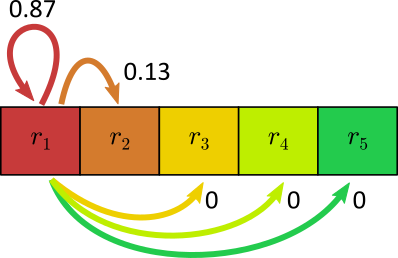

*Likelihoods for *$r_1$* clients. The only path out is to be moved into the high risk category.*

  **Pro-tip**: Set the first column of the matrix using `P(:,i) = [values]`. The "`:`" operator indicates that all rows will be selected. The index `i `determines the column index.

P(:,1) = [0.87 0.13 0 0 0]

$$P = \left(\begin{array}{ccccc} \frac{87}{100} & p_{1,2} & \frac{1}{100} & p_{1,4} & p_{1,5}\\ \frac{13}{100} & p_{2,2} & \frac{1}{25} & p_{2,4} & p_{2,5}\\ 0 & p_{3,2} & \frac{17}{20} & p_{3,4} & p_{3,5}\\ 0 & p_{4,2} & \frac{1}{10} & p_{4,4} & p_{4,5}\\ 0 & p_{5,2} & 0 & p_{5,4} & p_{5,5} \end{array}\right)$$

The rest of the transitions have been filled in below. 

P = [0.87 0.05 0.01 0.01 0.01;
     0.13 0.83 0.04 0.02 0.01;
     0.00 0.12 0.85 0.05 0.02;
     0.00 0.00 0.10 0.90 0.03;
     0.00 0.00 0.00 0.02 0.93]

P =     0.8700    0.0500    0.0100    0.0100    0.0100
    0.1300    0.8300    0.0400    0.0200    0.0100
         0    0.1200    0.8500    0.0500    0.0200
         0         0    0.1000    0.9000    0.0300
         0         0         0    0.0200    0.9300


  **Try. **The transition matrix can be visualized by a digraph. Run this section to visualize the transitions.

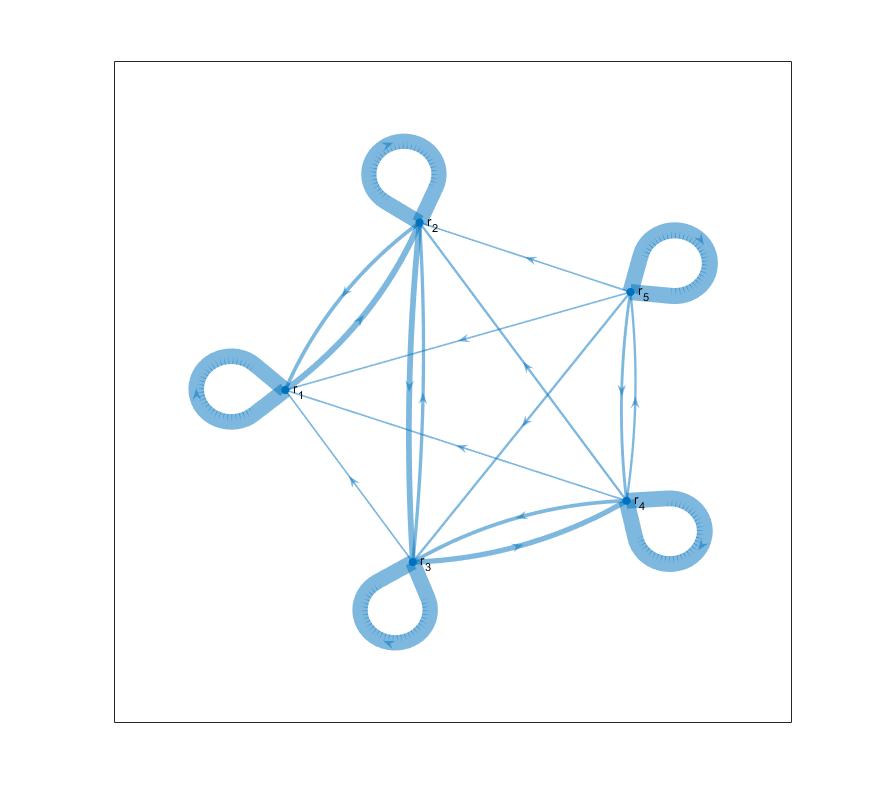

 
figure('position',[1,1,700,650])
G = digraph(P',["r_1","r_2","r_3","r_4","r_5"]);
plot(G,"linewidth",10*sqrt(G.Edges.Weight))

**Applying a transition matrix**

Suppose that, initially, the clients are equally distributed in all categories:

r = [0.2 0.2 0.2 0.2 0.2]' % Distribution of clients: 20% in each category

r =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


  **Task. **After one year, what will the new client classification be? Use matrix multiplication.

r1 = P*r

r1 =     0.1900
    0.2060
    0.2080
    0.2060
    0.1900


Repeated applications of the transition matrix will yield distributions of clients' risk categories. 

  **Task. **After 10 years, what wil be the risk distribution?

r10 = P^10*r

r10 =     0.1473
    0.2138
    0.2552
    0.2532
    0.1305


  **Task. **After 100 years, what wil the risk distribution be?

r100 = P^100*r

r100 =     0.1300
    0.2051
    0.2763
    0.3022
    0.0864


 **Reflect**

- Which categories end up with the largest share of clients? Which have the least?

- From a business standpoint, is this long-term distribution of clients desirable?

- Try starting with a different initial set of clients, $\mathbf{r}$. Does the resulting distribution change after many applications of the matrix?

**Eigen analysis**

The long-term behavior of a Markov chain model can be understood in terms of its eigenvalues and eigenvectors. A non-defective square matrix can diagonlized by computing its eigen decomposition:

    $\mathbf{P} =\mathbf{V \Lambda V}^{-1} $.

This implies that for the update after one year:

    $\mathbf{r}_{(1)} = \mathbf{V \Lambda V}^{-1} \mathbf{r}$.

To compute the state distribution after $n$ years, multiply by the transition matrix $n$ times:

    
$$\begin{array} {rl}
\mathbf{r}_{(n)} &= ( \mathbf{V \Lambda V}^{-1} )^n\mathbf{r}
\\
  &= (\mathbf{V \Lambda V}^{-1} )(\mathbf{V \Lambda V}^{-1} )\ldots (\mathbf{V \Lambda V}^{-1} )\mathbf{r}
\\
  &= \mathbf{V \Lambda}^n \mathbf {V}^{-1}  \mathbf{r}
\end{array}$$


** Exercise**. Compute the eigen decomposition of $\mathbf{P}$ and use it to evaluate the risk distribution $\mathbf{r}$ after 100 years.

r = [0.2 0.2 0.2 0.2 0.2]' % Distribution of clients: 20% in each category

r =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


% Compute r(100) here
[V,D] = eig(P)

V =     0.1584    0.0961   -0.2687    0.2313   -0.1712
   -0.4659   -0.1106   -0.4239    0.2112   -0.2874
    0.7295   -0.6165   -0.5711   -0.1169   -0.2996
   -0.4724    0.7624   -0.6246   -0.8091   -0.1262
    0.0503   -0.1314   -0.1785    0.4834    0.8845


D =     0.7424         0         0         0         0
         0    0.8140         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.8965         0
         0         0         0         0    0.9271


r100 = V*D^100*inv(V)*r

r100 =     0.1300
    0.2051
    0.2763
    0.3022
    0.0864


**Limit behavior**

Understanding the limiting behavior of the Markov chain model can be accomplished more directly by examining the eigenvalues contained in$\mathbf{\Lambda}$. Notice that for the transfer matrix, the eigenvalues have the property that $\lambda \leq1$:

D

D =     0.7424         0         0         0         0
         0    0.8140         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.8965         0
         0         0         0         0    0.9271


Using this property, you can show that, in the limit:

    
$$\lim_{n\rightarrow \infty} \mathbf{\Lambda}^n = 
\left(\begin{array}{ccccc}
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0
\end{array}\right)$$


% This defines the limit of the diagonal matrix
Dinf = zeros(5,5);
Dinf(3,3) = 1

Dinf =      0     0     0     0     0
     0     0     0     0     0
     0     0     1     0     0
     0     0     0     0     0
     0     0     0     0     0


  **Task. **Compute the limiting behavior as $n \to \infty$ of the system:

    
$$\begin{array} {rl}
\mathbf{r}_{(n)} = \mathbf{P}^{n}  \mathbf{r}
\end{array}$$
    

by computing the matrix $\mathbf{P}_\infty$ which satisfies

    $\mathbf{P}_\infty =   \lim_{n\rightarrow \infty} \mathbf{V \Lambda}^n \mathbf {V}^{-1}$.    

Pinf = V*Dinf*inv(V)

Pinf =     0.1300    0.1300    0.1300    0.1300    0.1300
    0.2051    0.2051    0.2051    0.2051    0.2051
    0.2763    0.2763    0.2763    0.2763    0.2763
    0.3022    0.3022    0.3022    0.3022    0.3022
    0.0864    0.0864    0.0864    0.0864    0.0864


  **Task. **Compute the limit distribution

    
$$\begin{array} {rl}
\mathbf{r}_{(\infty)} = \mathbf{P}^{\infty}  \mathbf{r}
\end{array}$$
    

rinf = Pinf*r

rinf =     0.1300
    0.2051
    0.2763
    0.3022
    0.0864


Run this section to plot the limit distribution as a bar graph using the [`bar`](https://www.mathworks.com/help/matlab/ref/bar.html) function.

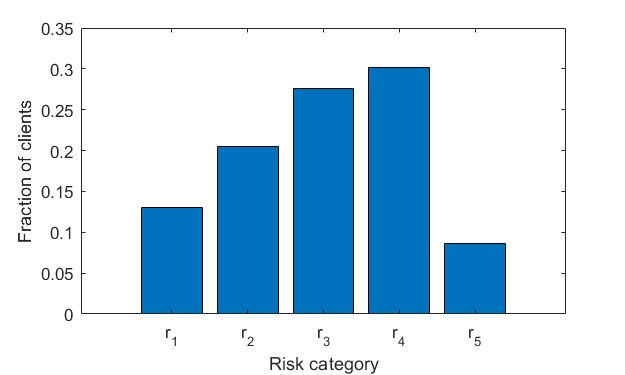

 
figure('position',[1,1,500,300])
bar(rinf)
set(gca,"xticklabel","r_" + strsplit(num2str(1:5)))
ylabel("Fraction of clients")
xlabel("Risk category")

 **Reflect**

- What relationship is there between the starting distribution $\mathbf{r}$ and the limit distribution? $\mathbf{P}_{\infty}$ defines this relationship.

- What is the business significance of $\mathbf{r}_\infty$?

### Analysis of a blood vessel network 

**ODE Model**

Blood vessels are often represented by lumped parameter models. In this description, a vessel is represented as a zero-dimensional chamber, having a pressure, compliance, and resistance to flow. Each vessel is modeled by an ordinary differential equation (ODE):

  
$$c \frac{dp}{dt} = \text{flow in} - \text{flow out}$$


where $p = p(t)$ is the pressure in the vessel.

The flow in depends on the pressure in the upstream vessel. The flow out depends similarly on the downstream vessel pressure. For example, if there is only one vessel upstream and downstream:

  
$$c \frac{dp}{dt} = \frac{p_{upstream} - p}{r_{in}} - \frac{p - p_{downstream}}{r_{out}}$$


Modeling a blood vessel network typically requires many equations of this form. Consider the (relatively small) system of 5 connected vessels shown.

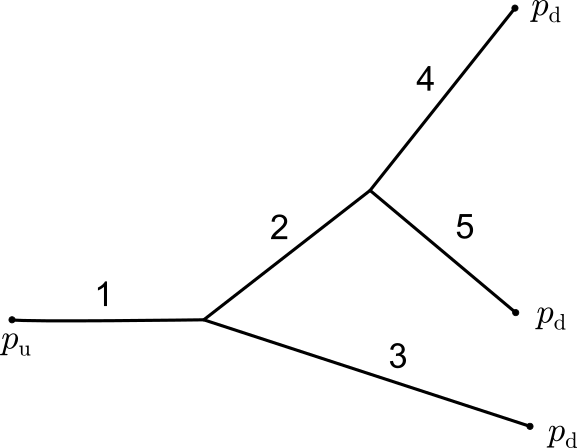

*Network of 5 connected vessels.*

To describe this system, you can define variables and constants for each vessel.

- $p_i = p_i(t)$: Pressure in the $i^{th}$ vessel at time $t$

- $c_i$: Compliance of the $i^{th}$ vessel

- $r_i$: Resistance of the $i^{th}$ vessel

The pressure entering the system is a constant upstream pressure, $p_u$. At the downstream end, a constant pressure $p_d$ is assumed. Resistance to flow out of the network is assumed to be a single constant value, $r_d%$$.

Under this description, the ODEs for the vessel pressures are:

    
$$c_1 \frac{dp_1}{dt} = \frac{p_u - p_1}{r_1}  - \frac{p_1 - p_2}{r_2} - \frac{p_1 - p_3}{r_3}$$


    
$$c_2 \frac{dp_2}{dt} = \frac{p_1 - p_2}{r_2} - \frac{p_2 - p_4}{r_4} - \frac{p_2 - p_5}{r_5}$$


    
$$c_3 \frac{dp_3}{dt} = \frac{p_1 - p_3}{r_3} - \frac{p_3- p_d}{r_d}$$


    
$$c_4 \frac{dp_4}{dt} = \frac{p_2 - p_4}{r_4} - \frac{p_4 - p_d}{r_d}$$


    
$$c_5 \frac{dp_5}{dt} = \frac{p_2 - p_5}{r_5} - \frac{p_5-p_d}{r_d}$$


**Matrix representation of the ODE system**

Defining the solution vector $\mathbf{p}$:

    
$$\mathbf{p} = \left(\matrix{p_1 \cr p_2 \cr p_3 \cr p_4 \cr p_5 }\right)$$


allows the ODE system to be written in matrix form as

    $\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$.

** Exercise**. Derive the form of the matrices $\mathbf{C}$ and $\mathbf{R}$ as well as the constant vector $\mathbf{f}$.

**Deriving the **$\mathbf{R}$** and **$\mathbf{f}$** using symbolic computations**

You can derive the coefficient matrix $\mathbf{R}$ and constant vector $\mathbf{f}$ by hand, but this task tedius and prone to errors. As an alternative, you can use the Symbolic Math Toolbox to derive the matrix form of the system. In this section, this workflow is demonstrated.

First, define the RHS of the equations as a vector using symbolic variables:

p = sym("p",[5,1]);
r = sym("r",[5,1]);
syms p_u p_d r_d 
RHS = [  (p_u - p(1))/r(1) - (p(1)- p(2))/r(2) - (p(1)-p(3))/r(3);
         (p(1) - p(2))/r(2) - (p(2)-p(4))/r(4) - (p(2)-p(5))/r(5);
         (p(1)-p(3))/r(3) - (p(3)-p_d)/r_d;
         (p(2)-p(4))/r(4) - (p(4)-p_d)/r_d;
         (p(2)-p(5))/r(5) - (p(5)-p_d)/r_d                   ];
RHS = expand(RHS)

$$RHS = \left(\begin{array}{c} \frac{p_{2}}{r_{2}}-\frac{p_{1}}{r_{2}}-\frac{p_{1}}{r_{3}}-\frac{p_{1}}{r_{1}}+\frac{p_{3}}{r_{3}}+\frac{p_{u}}{r_{1}}\\ \frac{p_{1}}{r_{2}}-\frac{p_{2}}{r_{2}}-\frac{p_{2}}{r_{4}}-\frac{p_{2}}{r_{5}}+\frac{p_{4}}{r_{4}}+\frac{p_{5}}{r_{5}}\\ \frac{p_{1}}{r_{3}}-\frac{p_{3}}{r_{3}}-\frac{p_{3}}{r_{d}}+\frac{p_{d}}{r_{d}}\\ \frac{p_{2}}{r_{4}}-\frac{p_{4}}{r_{4}}-\frac{p_{4}}{r_{d}}+\frac{p_{d}}{r_{d}}\\ \frac{p_{2}}{r_{5}}-\frac{p_{5}}{r_{5}}-\frac{p_{5}}{r_{d}}+\frac{p_{d}}{r_{d}} \end{array}\right)$$

In order to solve for $\mathbf{R}$ and $\mathbf{f}$ in MATLAB, set the RHS equal to zero, and then factor the system using the [`equationsToMatrix`](https://www.mathworks.com/help/symbolic/equationstomatrix.html) function: 

eqns = RHS == 0

$$eqns = \left(\begin{array}{c} \frac{p_{2}}{r_{2}}-\frac{p_{1}}{r_{2}}-\frac{p_{1}}{r_{3}}-\frac{p_{1}}{r_{1}}+\frac{p_{3}}{r_{3}}+\frac{p_{u}}{r_{1}}=0\\ \frac{p_{1}}{r_{2}}-\frac{p_{2}}{r_{2}}-\frac{p_{2}}{r_{4}}-\frac{p_{2}}{r_{5}}+\frac{p_{4}}{r_{4}}+\frac{p_{5}}{r_{5}}=0\\ \frac{p_{1}}{r_{3}}-\frac{p_{3}}{r_{3}}-\frac{p_{3}}{r_{d}}+\frac{p_{d}}{r_{d}}=0\\ \frac{p_{2}}{r_{4}}-\frac{p_{4}}{r_{4}}-\frac{p_{4}}{r_{d}}+\frac{p_{d}}{r_{d}}=0\\ \frac{p_{2}}{r_{5}}-\frac{p_{5}}{r_{5}}-\frac{p_{5}}{r_{d}}+\frac{p_{d}}{r_{d}}=0 \end{array}\right)$$

[A,b] = equationsToMatrix(eqns,p);

If you consult the [documentation](https://www.mathworks.com/help/symbolic/equationstomatrix.html), you will find that `equationsToMatrix` function solves for the factorization in the form $\mathbf{A}\mathbf{x} = \mathbf{b}$. For our system, this implies that

R = A

$$R = \left(\begin{array}{ccccc} -\frac{1}{r_{1}}-\frac{1}{r_{2}}-\frac{1}{r_{3}} & \frac{1}{r_{2}} & \frac{1}{r_{3}} & 0 & 0\\ \frac{1}{r_{2}} & -\frac{1}{r_{2}}-\frac{1}{r_{4}}-\frac{1}{r_{5}} & 0 & \frac{1}{r_{4}} & \frac{1}{r_{5}}\\ \frac{1}{r_{3}} & 0 & -\frac{1}{r_{3}}-\frac{1}{r_{d}} & 0 & 0\\ 0 & \frac{1}{r_{4}} & 0 & -\frac{1}{r_{4}}-\frac{1}{r_{d}} & 0\\ 0 & \frac{1}{r_{5}} & 0 & 0 & -\frac{1}{r_{5}}-\frac{1}{r_{d}} \end{array}\right)$$

f = -b

$$f = \left(\begin{array}{c} \frac{p_{u}}{r_{1}}\\ 0\\ \frac{p_{d}}{r_{d}}\\ \frac{p_{d}}{r_{d}}\\ \frac{p_{d}}{r_{d}} \end{array}\right)$$

The compliance matrix $\mathbf{C}$ is simply the diagonal matrix of the compliances

C = diag(sym("c",[5,1]))

$$C = \left(\begin{array}{ccccc} c_{1} & 0 & 0 & 0 & 0\\ 0 & c_{2} & 0 & 0 & 0\\ 0 & 0 & c_{3} & 0 & 0\\ 0 & 0 & 0 & c_{4} & 0\\ 0 & 0 & 0 & 0 & c_{5} \end{array}\right)$$

The final matrix form of the system $\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$ is therefore equivalent to:


$$\left( \matrix{ 
c_1 & 0 & 0 &  0 & 0 
 \cr
 0 & c_2 & 0  & 0 & 0
 \cr 
0 & 0 & c_3 & 0 & 0
 \cr 
0 & 0 & 0 & c_4 & 0
\cr
0 & 0 & 0 & 0 & c_5
}\right)
\left(\matrix{\frac{dp_1}{dt} \cr \frac{dp_2}{dt}\cr \frac{dp_2}{dt}\cr \frac{dp_4}{dt} \cr \frac{dp_5}{dt}}\right)
=
\left(\begin{array}{ccccc}
-\frac{1}{r_1 }-\frac{1}{r_2 }-\frac{1}{r_3 } & \frac{1}{r_2 } & \frac{1}{r_3 } & 0 & 0\\
\frac{1}{r_2 } & -\frac{1}{r_2 }-\frac{1}{r_4 }-\frac{1}{r_5 } & 0 & \frac{1}{r_4 } & \frac{1}{r_5 }\\
\frac{1}{r_3 } & 0 & -\frac{1}{r_3 }-\frac{1}{r_d } & 0 & 0\\
0 & \frac{1}{r_4 } & 0 & -\frac{1}{r_4 }-\frac{1}{r_d } & 0\\
0 & \frac{1}{r_5 } & 0 & 0 & -\frac{1}{r_5 }-\frac{1}{r_d }
\end{array}\right)
\left(\matrix{p_1 \cr p_2 \cr p_3 \cr p_4 \cr p_5 }\right)
+
\left(\begin{array}{c}
\frac{p_u }{r_1 }\\
0\\
\frac{p_d }{r_d }\\
\frac{p_d }{r_d }\\
\frac{p_d }{r_d }
\end{array}\right)$$


**Numerical solution to the ODE system**

The ODE system can be solved for a particular set of constants in MATLAB using a numeric ODE solver. 

  **Try. **Define the parameters below and then solve the system by running the section.

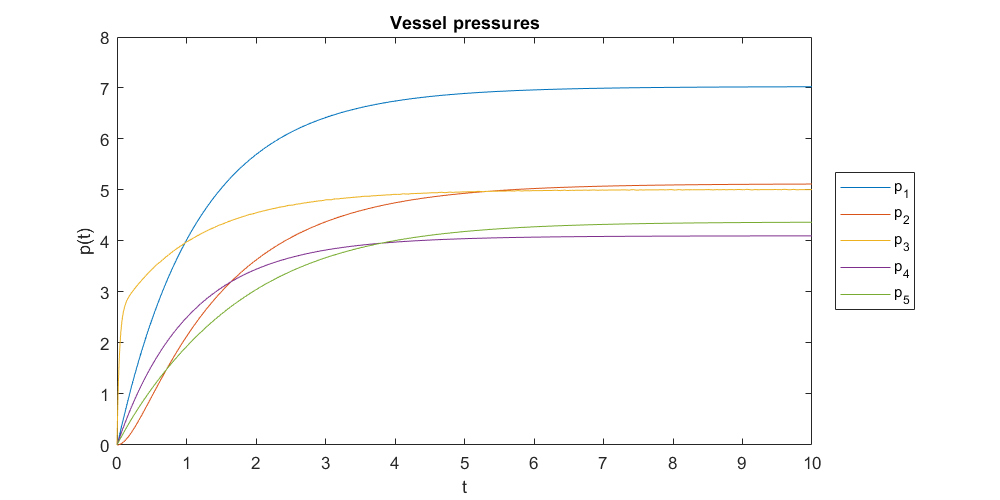

% Define the vessel resistances
r = [1 2 1 5 1];
% Define the vessel compliances
c = [2 0.4 0.1 2 3];
% Define the other constants
pu = 10;   % Upstream pressure
pd = 4;    % Downstream pressure
rd = 0.5;  % Outflow resistance
% Initial conditions
p0 = [0 0 0 0 0];
% Simulation duration
tf = 10;
 

odeFunc = @(t,p)vesselODEFunc(t,p,c,r,pu,pd,rd);
[t,p] = ode45(odeFunc,[0,tf],p0);
figure("position",[1,1,800,400])
plot(t,p)
legend("p_{" + strsplit(num2str(1:5)) + "}",'Location','EastOutside')
title("Vessel pressures")
xlabel('t')
ylabel('p(t)')

**Steady state solution**

The numeric solution of the ODE system reaches a steady state over time input and output pressures are constant. You can solve for this state.

** Exercise**. Solve for the steady state of the general ODE system (i.e, without specifying the constants).

  **Task**. The system is in a steady state when $\frac{d\mathbf{p}}{dt} = 0$. Solve for $\mathbf{p}$ in terms of $\mathbf{C}$, $\mathbf{R}$, and $\mathbf{f}$ in this state.

**Solution.**

    
$$\begin{array}{rl}
\mathbf{C} \cdot \mathbf{0}&= \mathbf{R}\mathbf{p} + \mathbf{f}
\\
\mathbf{0} &= \mathbf{R}\mathbf{p} + \mathbf{f}
\\
\mathbf{R}\mathbf{p} &= - \mathbf{f}
\end{array}$$


  **Task**. Use the symbolic commands to compute the steady state $\mathbf{p$. Note that $\mathbf{C}$, $\mathbf{R}$, and $\mathbf{f}$ have been defined in the previous sections.

p_steady = R\-f

** Exercise**. Solve for the steady state of the specific ODE system by performing the tasks.

  **Task**. Create an anonymous function for the symbolic expression in `p_steady` by applying the [`matlabFunction`](https://www.mathworks.com/help/symbolic/matlabfunction.html) function using the syntax

pFunction = matlabFunction(p_steady)

pFunction = function_handle with value:
    @(p_d,p_u,r1,r2,r3,r4,r5,r_d)[(p_u.*r_d.^3+p_d.*r1.*r_d.^2.*3.0+p_u.*r2.*r_d.^2.*2.0+p_u.*r3.*r_d.^2+p_u.*r4.*r_d.^2+p_u.*r5.*r_d.^2+p_d.*r1.*r2.*r4+p_d.*r1.*r2.*r5+p_d.*r1.*r3.*r4+p_d.*r1.*r3.*r5+p_d.*r1.*r4.*r5+p_u.*r2.*r3.*r4+p_u.*r2.*r3.*r5+p_u.*r3.*r4.*r5+p_d.*r1.*r2.*r_d.*2.0+p_d.*r1.*r3.*r_d.*2.0+p_d.*r1.*r4.*r_d.*2.0+p_d.*r1.*r5.*r_d.*2.0+p_u.*r2.*r3.*r_d.*2.0+p_u.*r2.*r4.*r_d+p_u.*r2.*r5.*r_d+p_u.*r3.*r4.*r_d+p_u.*r3.*r5.*r_d+p_u.*r4.*r5.*r_d)./(r1.*r_d.^2.*3.0+r2.*r_d.^2.*2.0+r3.*r_d.^2+r4.*r_d.^2+r5.*r_d.^2+r_d.^3+r1.*r2.*r4+r1.*r2.*r5+r1.*r3.*r4+r1.*r3.*r5+r2.*r3.*r4+r1.*r4.*r5+r2.*r3.*r5+r3.*r4.*r5+r1.*r2.*r_d.*2.0+r1.*r3.*r_d.*2.0+r1.*r4.*r_d.*2.0+r2.*r3.*r_d.*2.0+r1.*r5.*r_d.*2.0+r2.*r4.*r_d+r2.*r5.*r_d+r3.*r4.*r_d+r3.*r5.*r_d+r4.*r5.*r_d);(p_u.*r_d.^3+p_d.*r1.*r_d.^2.*3.0+p_d.*r2.*r_d.^2.*2.0+p_u.*r3.*r_d.^2+p_u.*r4.*r_d.^2+p_u.*r5.*r_d.^2+p_d.*r1.*r2.*r4+p_d.*r1.*r2.*r5+p_d.*r1.*r3.*r4+p_d.*r1.*r3.*r5+p_d.*r2.*r3.*r4+p_d.*r1.

  **Task**. Use the generated function to compute the specific steady state for constants defined above in `r`, `c`, `pu`, `pd`, and `rd`. Note that the order of the function inputs is listed at the beginning of the anonymous function.

pFunction(pd,pu,r(1),r(2),r(3),r(4),r(5),rd)

ans =     7.0284
    5.1229
    5.0095
    4.1021
    4.3743


 **Reflect**

- Does the steady state solution match the long term behavior of the numeric solution of the ODE?

- Try adjusting the constants used in the numeric solution. Does the steady state behavior still match?

- For very large ODE systems, the symbolic method for solving for the steady state is impractical. How would you adjust this workflow so that you could solve for the steady state of a larger system without performing the algebra by hand?

**Stability analysis**

In a typical homogeneous ODE stability analysis, you analyze a linear system in matrix form:

    $\frac{d\mathbf{x}}{dt} = \mathbf{A}\mathbf{x}$,

where $\mathbf{A}$ is a constant coefficient matrix. In this representation, the eigenvalues of $\mathbf{A}$ determine the stability of the solutions. Further, it can be shown that all of the solutions are linear combinations of the eigenvectors $\mathbf{v}_i$:

    
$$\mathbf{x}(t) = \sum_i \alpha_i \mathbf{v}_i e^{\lambda_i t}$$


The characterstics of each eigenvalue $\lambda_i$ determines the stability of that eigemode. 

- If $\text{Re}(\lambda_i)>0$, the mode grows exponentially

- If $\text{Re}(\lambda_i)<0$, the mode decays exponentially

- If $\text{Re}(\lambda_i)=0$ and $\text{Im}(\lambda_i) \neq 0$, the mode oscillates

** Exercise**. Show that

    
$$\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$$


can be written in the form

    $\frac{d\mathbf{u}}{dt} = \mathbf{A}\mathbf{u}$, 

so that a standard linear stability analysis may be used.

The equivalent form of the system is

    
$$\frac{d\mathbf{u}}{dt} = \mathbf{A} \mathbf{u}$$


with $\mathbf{A} = \mathbf{C}^{-1} \mathbf{R}$ and $\mathbf{u} =\mathbf{p} -\mathbf{R}^{-1}\mathbf{f}$. 

** Exercise**. In this exercise, you will perform a linear stability analysis on the blood vessel ODE system.

Specific $\mathbf{C}$, $\mathbf{R}$, and $\mathbf{f}$ are defined here in MATLAB variables `Cs`, `Rs`, and `fs` using the constants from earlier in the example. 

Cs = diag(c)

Cs =     2.0000         0         0         0         0
         0    0.4000         0         0         0
         0         0    0.1000         0         0
         0         0         0    2.0000         0
         0         0         0         0    3.0000


Rfunc = matlabFunction(R);
Rs = Rfunc(r(1),r(2),r(3),r(4),r(5),rd)

Rs =    -2.5000    0.5000    1.0000         0         0
    0.5000   -1.7000         0    0.2000    1.0000
    1.0000         0   -3.0000         0         0
         0    0.2000         0   -2.2000         0
         0    1.0000         0         0   -3.0000


fFunc = matlabFunction(f);
fs = fFunc(pd,pu,r(1),rd)

fs =     10
     0
     8
     8
     8


  **Task**. Define the matrix $\mathbf{A}$ using the constant matrices just defined.

A = inv(Cs)*Rs

A =    -1.2500    0.2500    0.5000         0         0
    1.2500   -4.2500         0    0.5000    2.5000
   10.0000         0  -30.0000         0         0
         0    0.1000         0   -1.1000         0
         0    0.3333         0         0   -1.0000


  **Task**. Compute the eigen decomposition of $\mathbf{A}$.

[V,D] = eig(A)

V =     0.0173   -0.0702    0.3913   -0.8603    0.2174
   -0.0008    0.9925    0.6164   -0.0658   -0.0184
   -0.9999   -0.0276    0.1335   -0.2972    0.0752
    0.0000   -0.0285    0.1487   -0.1571   -0.9710
    0.0000   -0.0923    0.6535    0.3775    0.0624


D =   -30.1729         0         0         0         0
         0   -4.5853         0         0         0
         0         0   -0.6856         0         0
         0         0         0   -1.0581         0
         0         0         0         0   -1.0981


 **Reflect**

- Is the system stable for the auxiliary variable $\mathbf{u}$?

- Is the system also stable for the original variable $\mathbf{p}$? Show that your answer is the case using the definition of $\mathbf{u}$: $\mathbf{u} =\mathbf{p} -\mathbf{R}^{-1}\mathbf{f}$. 

- Show that the steady state solution of $\mathbf{p}$ is $-\mathbf{R}^{-1} \mathbf{f}$ using the analysis of $\mathbf{u}$.

Supporting functions for the linear circuits application

function showCircuitMatrices()
    syms R_1 R_2 R_3 R_4 R_5 V_1 V_2
    A = [0 R_1+R_2   0   0   0; 
         0       0 R_3 R_4   0;
         0       0  0  R_4 R_5;
         1      -1  1   -1   0;
         1      -1  0    0  -1]
    b = [V_1; -V_2; V_1; 0; 0]
end


Supporting functions for the connected masses application

function [t,x,xdot] = solveMassesODE(x0, tlim, n)
    % This function solves the ODE with n masses
    xdot0 = zeros(n,1);
    y0 = [xdot0;x0];
    
    A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
    odeFunc = @(t,y)odeStringMasses(t,y,A,n);
    [t,y] = ode45(odeFunc,tlim,y0);
    
    xdot = y(:,1:n);
    x = y(:,n+1:2*n);
end

function [dydt] = odeStringMasses(t,y,A,n)
    % The second order system has been reduced to a system of first order
    % equations: the variable y =[u;x] where u = x_dot.
    u = y(1:n);
    x = y(n+1:2*n);
    x_dot = u;
    u_dot = A*x;
    dydt = [u_dot; x_dot];    
end

function AForm(n)
    A = sym(diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1))
end

function animateODEMasses(tin,xin,Nframes)
    % This function plots the ODE result
    Nmass = size(xin,2); % Number of masses
    t = linspace(tin(1),tin(end),Nframes);
    x = interp1(tin,xin,t);
    
    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 0.6; % Mass width
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    
    xub = max(abs(x),[],"all")*1.3;
    h = w*(1200/325)*(2*xub/umax); % Height of masses
 
    % Loop to create the animation
    f = figure("Visible","On");    
    set(gcf,'position',[100 200 1200 800])   
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        for k = 1:Nmass
            % Plot masses
            umk = spacing*k -w;
            xm = x(j,k);
            rectangle("Position",[umk x(j,k)-h/2 w h],"FaceColor",colors(k,:))
            text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
                "center","color","w","fontsize",10)
            % Plot strings
            if(k == 1)
                plot([umk-spacing+w, umk],[0,x(j,k)],'k')
            else
                plot([umk-spacing+w, umk],[x(j,k-1),x(j,k)],'k')
            end
        end
        % Last string
        umk = umax;
        plot([umk-spacing+w, umax],[x(j,k),0],'k')

        hold off
        axis([0,umax,-xub,xub])
        ylabel("x")
        xlabel("reference axis")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"ko","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x(t) ")
        hold off
        box off
        drawnow
    end
    close(f);
end

function visualizeMasses(x)
    Nmass = length(x); % Number of masses
    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 0.6; % Mass width
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    
    xub = max(abs(x),[],"all")*1.3;
    h = w*(1200/325)*(2*xub/umax); % Height of masses
 
    % Loop to create the animation
    figure;
    set(gcf,'position',[100 200 1200 400])   
    hold on
    for k = 1:Nmass
        % Plot masses
        umk = spacing*k -w;
        xm = x(k);
        rectangle("Position",[umk x(k)-h/2 w h],"FaceColor",colors(k,:))
        text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
            "center","color","w","fontsize",10)
        % Plot strings
        if(k == 1)
            plot([umk-spacing+w, umk],[0,x(k)],'k')
        else
            plot([umk-spacing+w, umk],[x(k-1),x(k)],'k')
        end
    end
    % Last string
    umk = umax;
    plot([umk-spacing+w, umax],[x(k),0],'k')

    hold off
    axis([0,umax,-xub,xub])
    ylabel("x")
    xlabel("reference axis")
end


Supporting functions for blood vessel network application

function dpdt = vesselODEFunc(t,p,c,r,pu,pd,rd)
    dpdt = vesselODE(c(1),c(2),c(3),c(4),c(5),p(1),p(2),p(3),p(4),p(5),pd,pu,r(1),r(2),r(3),r(4),r(5),rd);
end
function vesselODE = vesselODE(c1,c2,c3,c4,c5,p1,p2,p3,p4,p5,p_d,p_u,r1,r2,r3,r4,r5,r_d)
    %    This function was generated by the Symbolic Math Toolbox version 8.6.
    vesselODE = [(p2./r2+p3./r3+p_u./r1-p1.*(1.0./r1+1.0./r2+1.0./r3))./c1;(p1./r2+p4./r4+p5./r5-p2.*(1.0./r2+1.0./r4+1.0./r5))./c2;(p1./r3+p_d./r_d-p3.*(1.0./r3+1.0./r_d))./c3;(p2./r4+p_d./r_d-p4.*(1.0./r4+1.0./r_d))./c4;(p2./r5+p_d./r_d-p5.*(1.0./r5+1.0./r_d))./c5];
end

Suppress unused suggestions

%#ok<*INUSL> 
%#ok<*NASGU> 
%#ok<*NOPRT>
%#ok<*UNRCH> 